# Identificazione dei parametri dinamici - calcolo dei parametri dinamici da una traiettoria

Carico Pinocchio

clear all;
close all;
clc;
pin=py.importlib.import_module('pinocchio');
numpy=py.importlib.import_module('numpy');

model_name="gantry_portal_sea_soft";
model = py.pinocchio.buildModelFromMJCF('../labauto_assignment_1_2026/' + model_name+"/rigid_model.xml");

Warning - Only texture with files are supported
Warning - Only texture with files are supported
Warning - Only texture with files are supported
Warning - Only texture with files are supported


model_data = model.createData();
dof=double(model.nq);

carico la matrice di cambio variabili $T$ e il rango $b$

load('../labauto_assignment_1_2026/' + model_name+"/regressorT.mat");

carico la traiettoria

% trajectory_name="trajectory_20260306173155";
% trajectory_name="trajectory_20260408005647";
trajectory_name="trajectory_20260428163743";
load('../labauto_assignment_1_2026/' + model_name+"\tests\"+trajectory_name+".mat")
if isrow(time) % ensure the time is a column
    time=time';
end

Visto che i dati sono rumorosi e devo calcolare le accelerazioni utilizzo un filtro di Savitzky-Golay, è importante filtrate tutti i dati nello stesso modo per evitare lag temporali fra ingresso e uscita.

window_size = 201; % Must be odd
poly_order = 3;   % Polynomial order
[~,g] = sgolay(poly_order,window_size);
dt=time(2)-time(1);

Filtro i dati

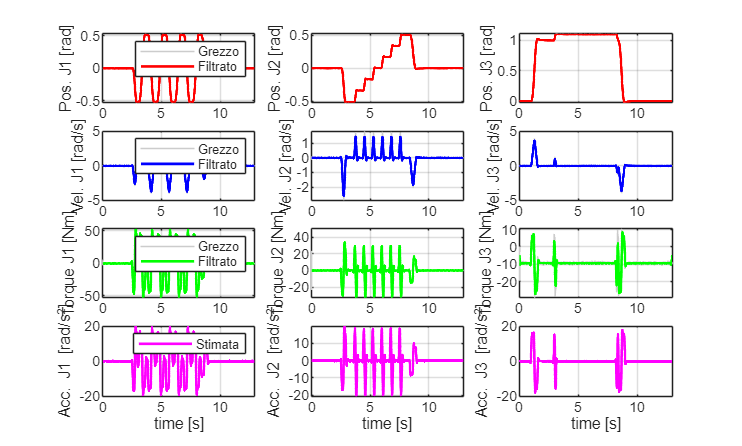

for idof=1:dof

    joint_position_filtered(:,idof) = conv(joint_position(:,idof), g(:,1), 'same'); % Smoothing using SG filter
    joint_velocity_filtered(:,idof) = conv(joint_velocity(:,idof), g(:,1), 'same'); % Smoothing using SG filter
    joint_torque_filtered(:,idof) = conv(joint_torque(:,idof), g(:,1), 'same'); % Smoothing using SG filter
    joint_acceleration_filtered(:,idof) = conv(joint_velocity(:,idof), g(:,2), 'same') / -dt; % First derivative using SG filter

    % Posizione
    subplot(4,dof,idof)
    plot(time, joint_position(:,idof), 'Color', [0.8 0.8 0.8]); hold on; % Grigio per il grezzo
    plot(time, joint_position_filtered(:,idof), 'r', 'LineWidth', 1.5);
    ylabel(sprintf('Pos. J%d [rad]',idof)); grid on;
    if idof == 1, legend('Grezzo','Filtrato'); end

    % Velocità
    subplot(4,dof,idof+dof)
    plot(time, joint_velocity(:,idof), 'Color', [0.8 0.8 0.8]); hold on;
    plot(time, joint_velocity_filtered(:,idof), 'b', 'LineWidth', 1.5);
    ylabel(sprintf('Vel. J%d [rad/s]',idof)); grid on;
    if idof == 1, legend('Grezzo','Filtrato'); end

    % Coppia
    subplot(4,dof,idof+2*dof)
    plot(time, joint_torque(:,idof), 'Color', [0.8 0.8 0.8]); hold on;
    plot(time, joint_torque_filtered(:,idof), 'g', 'LineWidth', 1.5);
    ylabel(sprintf('Torque J%d [Nm]',idof)); grid on;
    if idof == 1, legend('Grezzo','Filtrato'); end

    % Accelerazione
    subplot(4,dof,idof+3*dof)
    plot(time, joint_acceleration_filtered(:,idof), 'm', 'LineWidth', 1.5);
    xlabel('time [s]');
    ylabel(sprintf('Acc. J%d [rad/s^2]',idof)); grid on;
    if idof == 1, legend('Stimata'); end
end

Calcolo il regressore sui dati sperimentali, scarto i primi secondi, prendo un dato ogni 10 per velocizzare l'algoritmo

A=[];
Y=[];

for idx=1000:10:size(joint_position,1)-1000
    % q_row = joint_position_filtered(idx,:);
    % v     = joint_velocity_filtered(idx,:);
    % a_row = joint_acceleration_filtered(idx,:);
    % 
    % % TEST: inversione convenzione asse 3
    % q_row(3) = -q_row(3);
    % v(3)     = -v(3);
    % a_row(3) = -a_row(3);
    % 
    % q_numpy = py.numpy.array(q_row);
    % v_numpy = py.numpy.array(v);
    % a_numpy = py.numpy.array(a_row);
    % 
    q_numpy=py.numpy.array(joint_position_filtered(idx,:));
    v=joint_velocity_filtered(idx,:);
    v_numpy=py.numpy.array(v);
    a_numpy=py.numpy.array(joint_acceleration_filtered(idx,:));

    Phi_dynamic=double(py.pinocchio.computeJointTorqueRegressor(model,model_data,q_numpy,v_numpy,a_numpy));
    Phi_friction=[diag(v) diag(tanh(50*v))];
    Phi=[Phi_dynamic,Phi_friction];

    A=[A;Phi];

    tau=joint_torque_filtered(idx,:)';
    %tau(3) = -tau(3);
    Y=[Y;tau];
end

Ottenuto il regressore, calcolo il regressore di base, dove $A_{tmp}=\left[
\begin{array}{cc}
A_b & \mathbf{0}
\end{array}
\right]=AT^{-1}=AT^{T}$

Atmp=A*T';
Ab=Atmp(:,1:b);

calcolo parametri base

pb=Ab\Y;

scelgo i parametri del nullo pari a zero.

pnull=zeros(size(A,2)-b,1);

calcolo i parametri dinamici

p=T'*[pb;pnull];

calcolo Y del modello

Ymodel=A*p;

Separo le predizioni per i singoli giunti

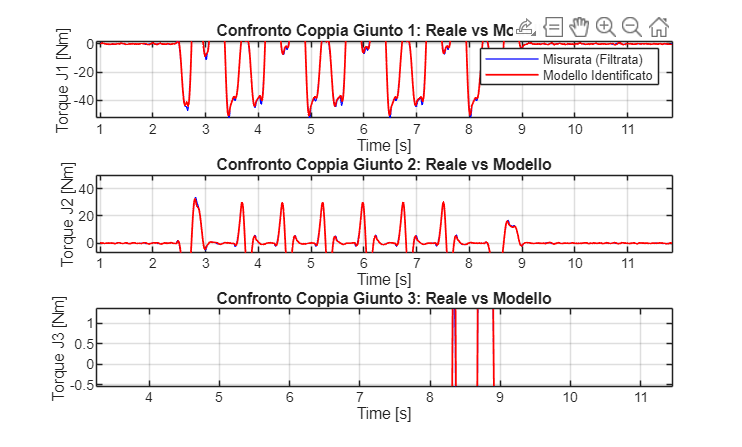

ymodel=reshape(Ymodel,dof,[])';
y=reshape(Y,dof,[])';

% figure('Name', 'Validazione Modello Dinamico', 'NumberTitle', 'off')
figure(2);
clf;

% Creiamo un vettore tempo ridotto coerente con il downsampling idx
time_reduced = time(1000:10:size(joint_position,1)-1000); 
for idof=1:dof
    subplot(dof, 1, idof)
    % Plot della coppia misurata filtrata (Blu)
    plot(time_reduced, y(:,idof), 'b', 'LineWidth', 0.7); 
    hold on;
    % Plot della coppia stimata dal modello (Arancione)
    plot(time_reduced, ymodel(:,idof), 'r', 'LineWidth', 1); 
    
    grid on;
    xlabel('Time [s]');
    ylabel(sprintf('Torque J%d [Nm]', idof));
    title(sprintf('Confronto Coppia Giunto %d: Reale vs Modello', idof));
    
    if idof == 1
        legend('Misurata (Filtrata)', 'Modello Identificato', 'Location', 'northeast');
    end
end


% figure(2)
% for idof=1:dof
% 
%     subplot(dof,1,idof)
%     plot([y(:,idof),ymodel(:,idof)])
%     xlabel('time')
%     ylabel(sprintf('torque joint %d',idof))
% end

Comparison tra coppia vera e coppie modello, in caso necessario filtrare di più. Con un sistema rigido si può ottenere un fitting buono.

Stampo i parametri in formato yaml

fprintf('model_parameters:\n');

model_parameters:


for ip=1:length(p)
    fprintf('- %f\n',p(ip));
end

- 0.965978
- -0.000000
- -0.000000
- -0.000000
- 0.000000
- -0.000000
- -0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.683348
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.957567
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- -0.116357
- -0.228924
- -0.038854
- 0.151473
- 0.162502
- 0.029351


%DEBUG saturazione torque
u = joint_torque;      % GREZZO
umax = [300 300 300];

u_peak = max(abs(u),[],1);
fprintf('Peak |u| = [%.3f %.3f %.3f]\n', u_peak(1), u_peak(2), u_peak(3));

Peak |u| = [48.818 32.686 29.338]



for alpha = [0.90 0.95 0.98 1.00]
    sat_mask = abs(u) >= alpha.*umax;
    sat_pct = 100*sum(sat_mask,1)/size(u,1);
    fprintf('Sat%% @ %.0f%% umax: [%.3f %.3f %.3f]\n', alpha*100, sat_pct(1), sat_pct(2), sat_pct(3));
end

Sat% @ 90% umax: [0.000 0.000 0.000]
Sat% @ 95% umax: [0.000 0.000 0.000]
Sat% @ 98% umax: [0.000 0.000 0.000]
Sat% @ 100% umax: [0.000 0.000 0.000]
